**!!! IMPORTANT !!!**

**Before running this Live script, run 1st demo ("a010_Basics_ParameterManagment_Solving_RunIDs.mlx") in order to get expected solutions in the CST project, if you haven't done so.**

Also, please read section "*Run ID and Run ID filter*" in that demo.

clc
clear

Connect to the project

CSTProject = 'CST\Single_dipole.cst';
CST = TCSTInterface();
CST.OpenProject(CSTProject);

Connected to project "E:\01_Toolboxes\CSTMWS-Matlab-Interface\Demos\CST\Single_dipole.cst"


# Result Tree and Tree Items

CST stores different results (such as S-parameters and radiation patterns) in so called Result Tree (in the CST GUI it is a panel named "Navigation Tree"). Each entry of the Result Tree is called Tree Item, which can be a folder (e.g. "1D Results\S-Parameters") or an actual result (e.g. "1D Results\S-Parameters\S1,1").

We can obtain the list of all available tree items under the specified root tree item by calling

RootTreeItem = '1D Results\Power';
CST.DisplayTreeItems(RootTreeItem);


-------------- Result tree under "1D Results\Power" ---------------
1D Results\Power\Excitation [1]
 | 1D Results\Power\Excitation [1]\Power Accepted per Port
 |  | 1D Results\Power\Excitation [1]\Power Accepted per Port\Port 1
 | 1D Results\Power\Excitation [1]\Power Accepted
 | 1D Results\Power\Excitation [1]\Power Outgoing all Ports
 | 1D Results\Power\Excitation [1]\Power Radiated
 | 1D Results\Power\Excitation [1]\Power Stimulated
-------------------------------------------------------------------



We can omit the input argument. In this case `RootTreeItem` will be set to `'1D Results'`:

CST.DisplayTreeItems();


-------------- Result tree under "1D Results" ---------------
1D Results\Port signals
 | 1D Results\Port signals\i1
 | 1D Results\Port signals\o1,1
1D Results\S-Parameters
 | 1D Results\S-Parameters\S1,1
1D Results\Reference Impedance
 | 1D Results\Reference Impedance\ZRef 1(1)
1D Results\Balance
 | 1D Results\Balance\Balance [1]
1D Results\Power
 | 1D Results\Power\Excitation [1]
 |  | 1D Results\Power\Excitation [1]\Power Accepted per Port
 |  |  | 1D Results\Power\Excitation [1]\Power Accepted per Port\Port 1
 |  | 1D Results\Power\Excitation [1]\Power Accepted
 |  | 1D Results\Power\Excitation [1]\Power Outgoing all Ports
 |  | 1D Results\Power\Excitation [1]\Power Radiated
 |  | 1D Results\Power\Excitation [1]\Power Stimulated
1D Results\Energy
 | 1D Results\Energy\Energy [1]
1D Results\Discrete Ports
 | 1D Results\Discrete Ports\Currents
 |  | 1D Results\Discrete Ports\Currents\Signals
 |  |  | 1D Results\Discrete Ports\Currents\Signals\Port 1 [1]
 |  | 1D Resul

If an output argument is specified, the method returns a cell arrays with all tree item paths instead of printing.

# Retrieving 1D results

Specify path to the result of interest in the Result Tree. You can copy it from the output of the `DisplayTreeItems` method shown above, In this demo we get accepted power.

TreeItem = '1D Results\Power\Excitation [1]\Power Accepted';

Get RunIDs for which this result exists

RunIDs = CST.GetResultIDsFromTreeItem(TreeItem);
s=sprintf('"%s", ',RunIDs{:}); fprintf('\n"%s" exists for %i RunIDs: %s.\n\n',TreeItem,length(RunIDs),s(1:end-2));


"1D Results\Power\Excitation [1]\Power Accepted" exists for 4 RunIDs: "3D:RunID:0", "3D:RunID:1", "3D:RunID:2", "3D:RunID:3".



Remark. In the CST documentstion "Run ID" is called "Result ID" sometimes, but it is basically the same.

Get 1D-result data from the specified TreeItem. The 3rd output parameter is the reference impedance, which is not relevant for the power results.

[x,y,~,RunIDs,Info] = CST.Get1DResultFromTreeItem(TreeItem);

Data for 1001 points will be read: X = 0.75, 0.7505, 0.751, ..., 1.25
Reading "1D Results\Power\Excitation [1]\Power Accepted", result id "3D:RunID:0"...
Reading "1D Results\Power\Excitation [1]\Power Accepted", result id "3D:RunID:1"...
Reading "1D Results\Power\Excitation [1]\Power Accepted", result id "3D:RunID:2"...
Reading "1D Results\Power\Excitation [1]\Power Accepted", result id "3D:RunID:3"...


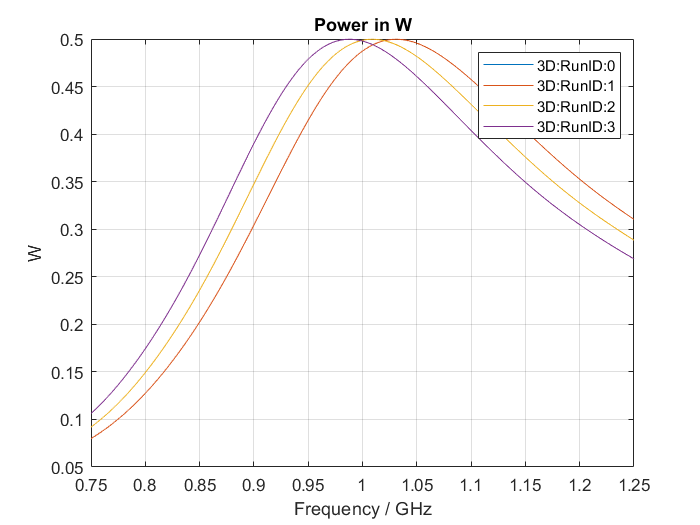

figure;  plot(x,y);  grid on;  legend(RunIDs)
xlabel(Info.XLabel);  ylabel(Info.YLabel);  title(Info.Title);

Same, but only for specific RunID.

% RunIDFilter = [1 3]; % get data for RunIDs 1 and 3
RunIDFilter = {'~3D:RunID:2'}; % exclude RunID=2;  RunIDFilter=-2 has same effect.
[x,y,~,RunIDs,Info] = CST.Get1DResultFromTreeItem(TreeItem, RunIDFilter);

Data for 1001 points will be read: X = 0.75, 0.7505, 0.751, ..., 1.25
Reading "1D Results\Power\Excitation [1]\Power Accepted", result id "3D:RunID:0"...
Reading "1D Results\Power\Excitation [1]\Power Accepted", result id "3D:RunID:1"...
Reading "1D Results\Power\Excitation [1]\Power Accepted", result id "3D:RunID:3"...


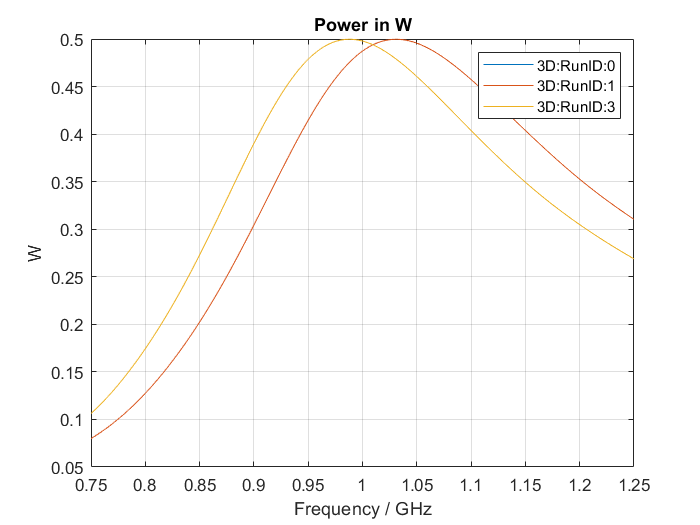

figure;  plot(x,y);  grid on;  legend(RunIDs)
xlabel(Info.XLabel);  ylabel(Info.YLabel);  title(Info.Title);

We can also get 1D-result only for specified *X* (*X* is frequency for this `TreeItem`). Note that *X* should be specified in the units like in CST plot. In this example `QueryX=1` means frequency = 1 GHz.

QueryX = 0.9:0.01:1; % just 11 frequency points from 0.9 to 1 GHz
[x,y,~,RunIDs,Info] = CST.Get1DResultFromTreeItem(TreeItem, RunIDFilter, QueryX);

Data for 11 points will be read: X = 0.9, 0.91, 0.92, ..., 1
Reading "1D Results\Power\Excitation [1]\Power Accepted", result id "3D:RunID:0"...
Reading "1D Results\Power\Excitation [1]\Power Accepted", result id "3D:RunID:1"...
Reading "1D Results\Power\Excitation [1]\Power Accepted", result id "3D:RunID:3"...


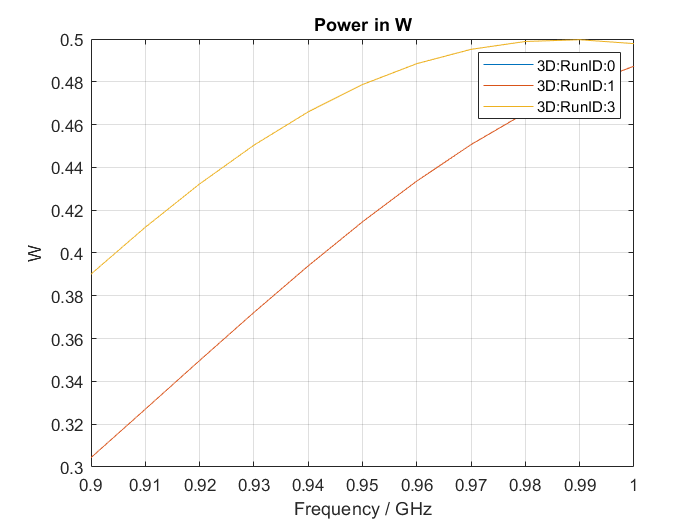

figure;  plot(x,y);  grid on;  legend(RunIDs)
xlabel(Info.XLabel);  ylabel(Info.YLabel);  title(Info.Title);

Some 1D-results can have an impedance attached. E.g. for S-parameters the attached impedance is the reference impedance. It is returned in the 3rd output argument.

TreeItem = '1D Results\S-Parameters\S1,1'; % Select S11 tree item
[x,y,Zref,RunIDs,Info] = CST.Get1DResultFromTreeItem(TreeItem);

Data for 1001 points will be read: X = 0.75, 0.7505, 0.751, ..., 1.25
Reading "1D Results\S-Parameters\S1,1", result id "3D:RunID:0"...
Reading "1D Results\S-Parameters\S1,1", result id "3D:RunID:1"...
Reading "1D Results\S-Parameters\S1,1", result id "3D:RunID:2"...
Reading "1D Results\S-Parameters\S1,1", result id "3D:RunID:3"...


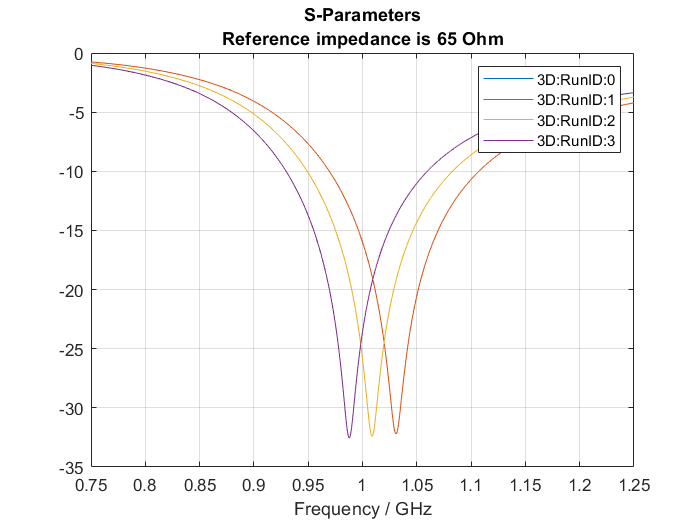

figure;  plot(x,20*log10(abs(y)));  grid on;  legend(RunIDs)
xlabel(Info.XLabel);  ylabel(Info.YLabel);  
title({Info.Title, sprintf('Reference impedance is %g Ohm',Zref)});

# Retrieving S-matrix

If **full S-parameters matrix **should be obtained, the `GetSParams` method can be used. The full syntax is 

It reads all children tree items under the branch '`1D Results\S-Parameters`' (ignoring Floquet ports if any exist) and arranges the data into a matrix with following indexing: 

-  6D-array: `S(m,mmode,n,nmode,iFreq,iRunID)`, if port(s) have several modes AND `PortMode` is not specified 

-  4D-array: `S(m,n,iFreq,iRunID)`, otherwise 

where `m `and `n` are port indices; `iFreq` is the frequency index, and; `iRunID` is the RunID index (see Result Navigator in the CST GUI).

All input parameters are optional and can be empty in order to read all available RunIDs/Rows/Columns/Modes/Frequencies:

[S, Freq, Zref, Info] = CST.GetSParams();

Data for 1001 frequencies will be read:  750 MHz, 750.5 MHz, 751 MHz, ..., 1.25 GHz
Reading "1D Results\S-Parameters\S1,1", result id "3D:RunID:0"...
Reading "1D Results\S-Parameters\S1,1", result id "3D:RunID:1"...
Reading "1D Results\S-Parameters\S1,1", result id "3D:RunID:2"...
Reading "1D Results\S-Parameters\S1,1", result id "3D:RunID:3"...


Now we plot $$S_{11}$$ as function of frequency for the 2nd RunID:

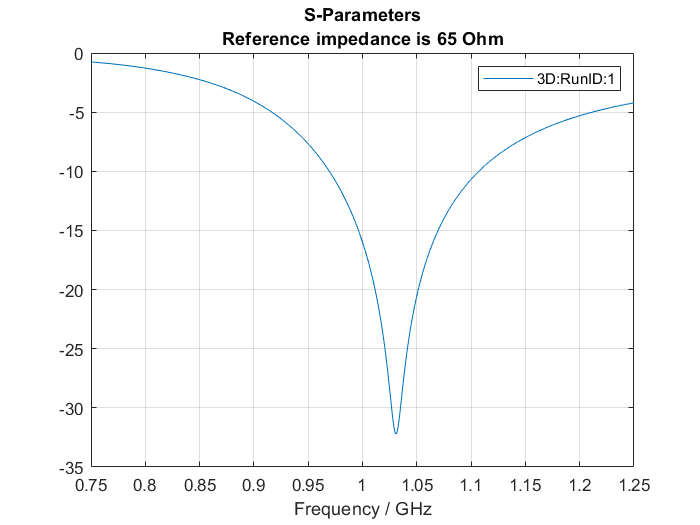

iRunID = 2;
figure;  
S11 = squeeze( S(1,1,:,iRunID) );   % complex S11
plot(Freq/1e9, 20*log10(abs(S11))); % we plot |S11| in dB 
grid on;  xlabel(Info.XLabel);  ylabel(Info.YLabel); legend(Info.ResultIDs{iRunID});
title({Info.Title, sprintf('Reference impedance is %g Ohm',Zref)});

Same, but now we read only $$S_{11}$$ for a given frequency `QueryFreq` and RunID 3 

RunIDFilter = 3;
QueryFreq = 1;  % as for Get1DResultFromTreeItem, QueryFreq here is in units like in the CST plot, i.e. [GHz] 
[S, Freq, Zref, Info] = CST.GetSParams(RunIDFilter,1,1,[],QueryFreq);

Data for 1 frequencies will be read:  1 GHz
Reading "1D Results\S-Parameters\S1,1", result id "3D:RunID:3"...


fprintf('\n|S11| @ f=%s for RunID %i is %g dB\n', TCSTInterface.FreqToString(Freq), RunIDFilter, 20*log10(abs(S)));


|S11| @ f=1 GHz for RunID 3 is -23.5701 dB


# Retrieving Z-matrix

Similarly, Z-matrix can be retrieved (if it is calculated) using 

which has similar syntax as `GetSParams` described above.